# Projeto de Controladores - Ball and Beam - Parte I

## Introdução

O sistema abaixo é conhecido como Ball and Beam. Nele uma bolinha é equilibrada sobre uma barra, atuada em uma das extremidades por um motor/conjunto de engrenagens e uma alavanca.

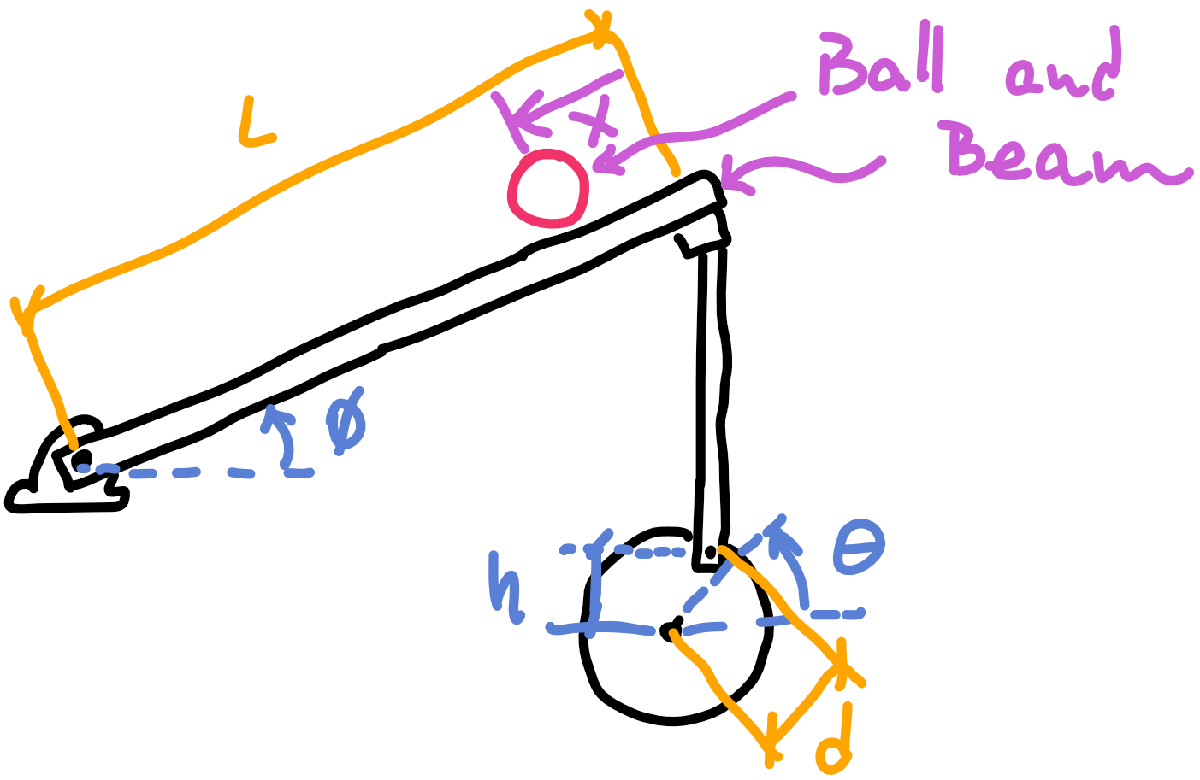

A equação diferencial que rege a dinâmica deste sistema é dada por:

$\frac{m\cdot g\cdot d}{L}\cdot \sin\left(\theta\left(t\right)\right)=\ddot{x}\left(t\right)\cdot\left(m+\frac{J}{R^2}\right)$    (1)

onde:

- $m=0,064\;\textrm{kg}$ é a massa da bola;

- $R=0,0127\;\mathrm{m}$ é o raio da bola;

- $J=4,129\cdot {10}^{-6} \;\textrm{kg}\cdot {\mathrm{m}}^{2\;}$ é o momento de inercia da bola;

- $d=0,0254\;\mathrm{m}$ é a distância de acionamento;

- $L=0,5\;\mathrm{m}$ é o comprimento da barra; e

- $$g = 9,81$\,m/s$ é a constante de aceleração da gravidade.

Vamos considerar como entrada do sistema a posição angular do servomotor $\theta \;\left(t\right)$ e como saída o deslocamento da bolinha sobre a barra $x\left(t\right)$.

Como podemos perceber, trata-se de uma equação diferencial não linear (função seno), e não conseguiríamos aplicar a transformada de Laplace para obter uma função de transferência. Entretanto, podemos linearizar esta equação diferencial e obter um modelo representativo da dinâmica nas proximidades de um ponto de equilíbrio.

Antes de prosseguir com a linearização, isolar $\ddot{x} \left(t\right)$ na Eq. (1),

$\ddot{x}\left(t\right)=\frac{m\cdot g\cdot d}{L\cdot\left(m+\frac{J}{R^2}\right)}\cdot \sin\left(\theta\left(t\right)\right)$    (2)

O processo de linearização de uma equação diferencial consiste em substituir uma função não linear por sua expansão em série de Taylor e truncar essa expansão no primeiro termo, que é linear. Para isso, devemos escolher um ponto de equilíbrio, definido por um valor de entrada e um valor de saída, em torno do qual faremos essa linearização. Faz todo sentido escolher $\theta_e =0$ já que quando o sistema estiver em repouso com a bolinha parada, esta será a orientação do servomotor. É fácil perceber que a aceleração $\ddot{x}$ será nula quando $\theta =\theta_e =0$.

O próximo passo é determinar a expansão em série de Taylor. Lembre-se que:


$$f\left(x-x_e \right)\approx f\left(x_e \right)+\frac{\textrm{df}\left(x_e \right)}{\textrm{dx}}\cdot \left(x-x_{e\;} \right)+\frac{1\;}{2!}\frac{d^2 f\left(x_e \right)}{{\textrm{dx}}^2 }\cdot {\left(x-x_{e\;} \right)}^2 +\frac{1\;}{3!}\frac{d^3 f\left(x_e \right)}{{\textrm{dx}}^3 }\cdot {\left(x-x_{e\;} \right)}^3 +\ldotp \ldotp \ldotp$$


Aplicando na Eq. (2) e truncando no termo linear,


$$\ddot{x}\left(t\right)=\frac{m\cdot g\cdot d}{L\cdot\left(m+\frac{J}{R^2}\right)}\cdot \left(\sin\left(\theta_e\right)+\cos\left(\theta_e\right)\cdot(\theta-\theta_e)\right)$$



$$\ddot{x}\left(t\right)=\frac{m\cdot g\cdot d}{L\cdot\left(m+\frac{J}{R^2}\right)}\cdot \left(\sin\left(0\right)+\cos\left(0\right)\cdot\theta\right)$$


$\ddot{x}\left(t\right)=\frac{m\cdot g\cdot d}{L\cdot\left(m+\frac{J}{R^2}\right)}\cdot \theta$    (3)

Comparando a Eq. (2) com a Eq. (3), o processo de linearização implicou em $\sin(\theta) \approx \theta$, para valores próximos ao ponto de equilíbrio. Observe no gráfico abaixo essa comparação.

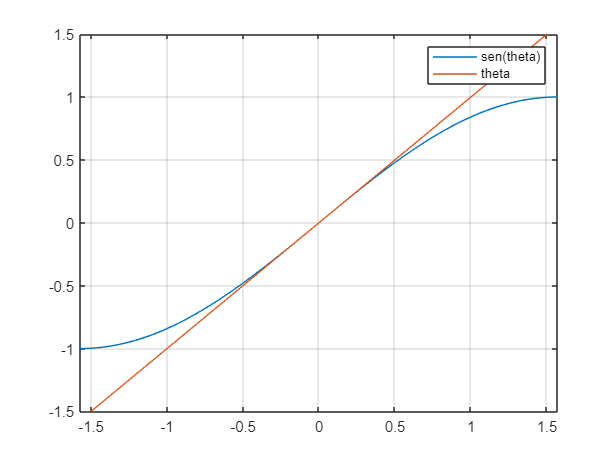

x = (-pi/2:0.01:pi/2);
y = sin(x);

plot(x,y,x,x);
legend("sen(theta)","theta");
grid on

xlim([-pi/2 pi/2])
ylim([-1.5 1.5])

Enfim, a equação diferencial linearizada para pequenos deslocamentos em torno de $\theta =0$ é

$\ddot{x}\left(t\right)=\frac{m\cdot g\cdot d}{L\cdot\left(m+\frac{J}{R^2}\right)}\cdot \theta(t)$    (4)

Aplicando transformada de Laplace na Eq. (4), a função de transferência, como entrada do sistema a posição angular do servomotor $\theta \;\left(t\right)$ e como saída o deslocamento da bolinha sobre a barra $x\left(t\right)$, resulta em

$\frac{X(s)}{\Theta(s)}=\frac{m\cdot g\cdot d}{L\cdot\left(m+\frac{J}{R^2}\right)\cdot s^2}$    (5)

Substituindo os valores do sistema teremos

$\frac{X(s)}{\Theta(s)}=\frac{0,356}{s^2}$    (6)

## Testar o sistema não linear

**a)** Execute o código abaixo para gerar os parâmetros da planta.

% Define s como uma função de transferência
s=tf('s');
% Define os parâmetros físicos do sistema
m = 0.0640;     % massa da bola [kg] 
R = 0.0127;     % raio da bola [m]
J = 4.1290e-06; % momento de inercia da bola [kg.m^2]
d = 0.0254;     % distancia de acionamento [m]
L = 0.5;        % comprimento da barra [m]
g = 9.81;       % constante de gravidade [m/s^2]

% define a função de transferência linearizada
G = (m*g*d)/(L*(m+J/R^2)) / (s^2);

**b)** Abra o modelo simulink `ballandbeam.slx`, e altere o ângulo de acionamento para observar o comportamento. Os limites de acionamento são $$\pm 1$\,rad$.

## Projeto de um controlador/compensador

Projete um controlador de posição para que a resposta ao degrau tenha sobressinal máximo de $5\,\%$ e tempo de acomodação $$\leq 4$\,s$.

**c)** Considerando que a planta é do tipo 2, qual deve ser o controlador?

**d)** Uma vez escolhido o controlador, determine os ganhos de forma analítica.

## Testar o controlador no sistema linear

**e)** Altere o código abaixo os ganhos que você determinou no item **d **e execute para gerar os parâmetros do controlador e verificar o desempenho no modelo linear.

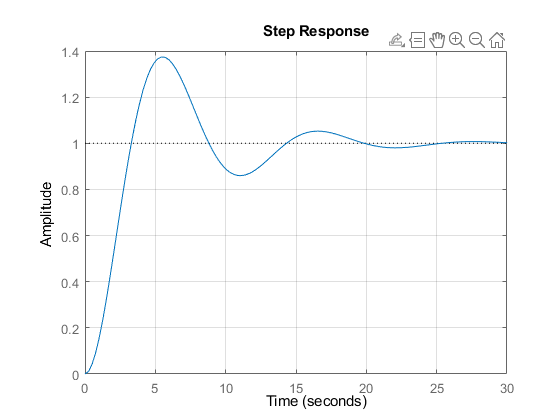

% Define os ganhos do compensador
Kp = 1.0; 
Kd = 1.0;

% define a função de transferência de malha fechada do P-D
Gmf = (Kp*G)/(1 + G*(Kd*s+Kp));
Gmf = minreal(Gmf);
% valida o controlador com a planta linearizada
step(Gmf); grid on;
set(gcf,'Visible','on');

**f) **Diante dos resultados:

- O tempo de acomodação é de fato o projetado?

- O percentual de sobressinal é de fato o projetado?

- Houve algum erro em regime permanente?

## Testar o controlador no sistema não linear

Salve o modelo simulink `ballandbeam.slx` como `ballandbeam_ctrl.slx` e altere o modelo para adicionar o seu controlador. Altere, também, o `Knob` de ângulo de acionamento, por uma sequência de pulsos que varie de $$0.1$\,m$ até $$0.4$\,m$ período $$16$\,s$ e largura de banda de $$50$\,\%$. Isso pode ser realizado com o bloco `pulse` somado com uma constante de `0.1`, conforme figura abaixo.

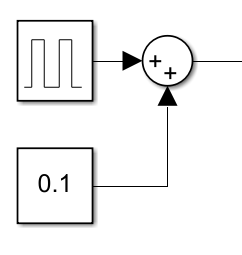

O limite da referência é o comprimento da barra $$L$$, isto é, $$(0,0-0,5)$\,m$.

Execute seu modelo e *aprecie (ou não)* o comportamento do controlador que você acabou de projetar.

**g) **Diante dos resultados:

- O tempo de acomodação é de fato o projetado?

- O percentual de sobressinal é de fato o projetado?

- Houve algum erro em regime permanente?

- Como ficou o esforço de controle? Sabendo que movimento $\theta \;\left(t\right)$ do servomotor é mecânicamente limitado em $\pm 1\;\textrm{rad}$, houve alguma satuação do atuador?

**h)** Caso tenha sido necessário alterar o controlador ou realizar um ajuste fino nos ganhos do compensador, quais são os novos ganhos?